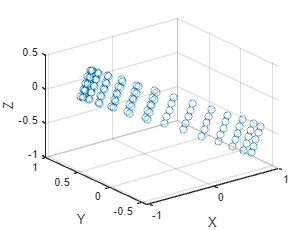

clear;clc;close all

azimuth = 5.768639;
elevation = 4.586836;
num = 20 ;
laynum = 5;
P1= [0.550556855589298;-0.253463233227619;0.569107251386041];
P2 = [-0.396475501724922;-0.251497221872904;-0.364682750821888];

r = 1;
x0 = r.*cos(azimuth).*cos(elevation);
y0 = r.*cos(azimuth).*sin(elevation);
z0 = r.*sin(azimuth);



Pl1 = [0,0,0];
Pl2 = [x0,y0,z0];


[xN1,yN1,zN1] = foot_of_perpendicular_from_a_point_to_a_line(P1,Pl1,Pl2);
[xN2,yN2,zN2] = foot_of_perpendicular_from_a_point_to_a_line(P2,Pl1,Pl2);


deltx = zeros(1,laynum);
delty = zeros(1,laynum);
deltz = zeros(1,laynum);

for i = 1:laynum
    lamuda = i/(laynum+1-i);
    deltx(i) =  (xN1+lamuda*xN2)/(1+lamuda);
    delty(i) =  (yN1+lamuda*yN2)/(1+lamuda);
    deltz(i) =  (zN1+lamuda*zN2)/(1+lamuda);
end


% 定义法向量
normal_vector = [x0, y0, z0];
% 检查法向量是否是单位向量，如果不是则归一化
if norm(normal_vector) ~= 1
    normal_vector = normal_vector / norm(normal_vector);
end

% 使用参数方程生成单位圆上的点

v = cross(normal_vector, [0, 0, 1]); % 找到与法向量垂直的一个向量
if norm(v) < eps % 如果法向量与 [0, 0, 1] 平行，则选择另一个向量
    v = cross(normal_vector, [0, 1, 0]);
end

v = v / norm(v); % 归一化向量
u = cross(v, normal_vector); % 创建另一个垂直向量

if v(1) > 0
    theta = linspace(-2*pi/3,2/3*pi,num);
else
    theta = linspace(pi/3,5/3*pi,num);
end

% 单位圆的参数方程
x_circle = cos(theta) * v(1) + sin(theta) * u(1);
y_circle = cos(theta) * v(2) + sin(theta) * u(2);
z_circle = cos(theta) * v(3) + sin(theta) * u(3);

Point_out = zeros(3,num*laynum);
for j = 1:laynum
    x_circle1 = x_circle + deltx(j);
    y_circle1 = y_circle + delty(j);
    z_circle1 = z_circle + deltz(j);
    Point_out(:,(j-1)*num+1:j*num) = [x_circle1;y_circle1;z_circle1];
end






XX = Point_out(3,:);
YY = Point_out(1,:);
ZZ = Point_out(2,:);
scatter3(XX,YY,ZZ)
xlabel('X')
ylabel('Y')
zlabel('Z')